**The simulations for the gene-specific RS model.**

**For Figure 6d.**

% Basic paramters
load ../Parameter_determination/Basic_parameters.mat

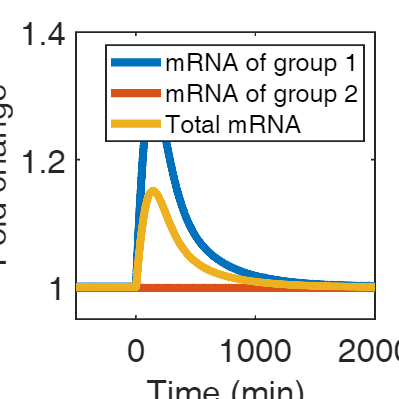

para0=para_opt;


% Initialization of two RS models
load ../Solve_values/Solve_values.mat % Symbolic solutions
syms_solve=[Xn_pre,Xc_pre,Xp_pre,Yn_pre,Yp_pre];
syms k0 Kx Ky Km am ax ay bm bx Xt Yt Vn Vc Kv
para_sym=[k0 Kx Ky Km am ax ay bm bx Xt Yt Vn Vc Kv];
para_num=[para0,2.8,37.2,5.8262];
%para:[k0 Kx Ky Km am ax ay bm bx Xt Yt]
temp1=double(subs(syms_solve,para_sym,para_num));% Xn Xc Xp Yn Yp
temp1=temp1(~any(temp1<0,2),:);
temp2=[2.8*para0(7)/para0(5),37.2*para0(9)/para0(8)];% mn mc
y_wt=[temp2,temp1]; %[mn mc Xn Xc Xp Yn Yp]

%[mn mc Xn Xc Xp Yn Yp]
mn10=y_wt(1);
mc10=y_wt(2);
mn20=y_wt(1);
mc20=y_wt(2);
Xn10=y_wt(3);
Xc10=y_wt(4);
Xp10=y_wt(5);
Xn20=y_wt(3);
Xc20=y_wt(4);
Xp20=y_wt(5);
Yn10=y_wt(6);
Yp10=y_wt(7);
Yn20=y_wt(6);
Yp20=y_wt(7);

%para:[k0 Kx Ky Km am ax ay bm bx Xt Yt]
k01=para0(1);
k02=para0(1);
Kx1=para0(2);
Kx2=para0(2);
Ky1=para0(3);
Ky2=para0(3);
Km1=para0(4);
Km2=para0(4);
am1=para0(5);
am2=para0(5);
ax1=para0(6);
ax2=para0(6);
ay1=para0(7);
ay2=para0(7);
bm1=para0(8);
bm2=para0(8);
bx1=para0(9);
bx2=para0(9);
Vn=2.8;
Vc=37.2;
Kv=5.8262;


% Calculate the homeostatic values
%y:[mn1 mc1 mn2 mc2 Xn1 Xc1 Xp1 Xn2 Xc2 Xp2 Yn Yp]
para1=[k01 k02 Kx1 Kx2 Ky1 Ky2 Km1 Km2 am1 am2 ax1 ax2 ay1 ay2 bm1 bm2 bx1 bx2 Vn Vc Kv];
y_ini=[mn10 mc10 mn20 mc20 Xn10 Xc10 Xp10 Xn20 Xc20 Xp20 Yn10 Yp10 Yn20 Yp20];

tspan=[1:1:3e4];
[~,y_tot]=ode15s(@(t,y)diffun(y,para1),tspan,y_ini);
y_ini2=y_tot(end,:);



% Depletion of the Xc of one of the RS models
y_ini3=y_ini2;
y_ini3(6)=y_ini2(6)/10;%Xc1


% Calculate the values after perturbation
tspan=[1:1:3e4];
[~,y_tot2]=ode15s(@(t,y)diffun(y,para1),tspan,y_ini3);

y_all=[y_tot(end-5e3:end,:);y_tot2(1:5e3,:)];

%y:[mn mc Xn Xc Xp Yn Yp Pn Pnb Pc Pcb]
m1_all=y_all(:,1)+y_all(:,2);
m2_all=y_all(:,3)+y_all(:,4);
m_all=m1_all+m2_all;


% Plot
colors=["#0072BD"
    "#D95319"
    "#EDB120"
    "#7E2F8E"
    "#77AC30"
    "#4DBEEE"
    "#A2142F"
    '#FF0000'
    '#00FF00'
    '#0000FF'
    '#00FFFF'
    '#FF00FF'
    '#FFFF00'
    '#000000'
    '#FFFFFF'];


fig=figure;
set(fig,'Position',[300 100 700 700]);
ax1=axes('position', [0.19 0.2 0.75 0.72]);


scale_time=(1:length(m_all))-5e3;
p1=plot(scale_time,m1_all/m1_all(1)+0.001,'-', ...
    "LineWidth",5, ...
    "Color",colors(1),...
    "DisplayName","mRNA of group 1");
hold on
p2=plot(scale_time,m2_all/m2_all(1)-0.001,'-', ...
    "LineWidth",5, ...
    "Color",colors(2),...
    "DisplayName","mRNA of group 2");
hold on
p3=plot(scale_time,m_all/m_all(1),'-', ...
    "LineWidth",5, ...
    "Color",colors(3),...
    "DisplayName","Total mRNA");
hold off
xlim([-500,2e3])
ylim([0.95,1.4])
set(ax1,'LabelFontSizeMultiplier',1.2,'linewidth',1);
set(gca,'FontSize',20)
legend([p1 p2 p3],"Interpreter","tex","FontSize",15)
xlabel('Time (min)','interpreter','tex','FontSize',20);
ylabel('Fold change','interpreter','tex','FontSize',20);

function dydt = diffun(y,para)
%%% Differential equations of 2 RS models

%y:[mn1 mc1 mn2 mc2 Xn1 Xc1 Xp1 Xn2 Xc2 Xp2 Yn1 Yp1 Yn2 Yp2]
mn1=y(1);
mc1=y(2);
mn2=y(3);
mc2=y(4);
Xn1=y(5);
Xc1=y(6);
Xp1=y(7);
Xn2=y(8);
Xc2=y(9);
Xp2=y(10);
Yn1=y(11);
Yp1=y(12);
Yn2=y(13);
Yp2=y(14);


%para:[k0 Kx1 Kx2 Ky1 Ky2
%      Km am ax1 ax2 ay1 ay2
%      bm1 bm2 bx1 bx2 Vn Vc Kv]

k01=para(1);
k02=para(2);
Kx1=para(3);
Kx2=para(4);
Ky1=para(5);
Ky2=para(6);
Km1=para(7);
Km2=para(8);
am1=para(9);
am2=para(10);
ax1=para(11);
ax2=para(12);
ay1=para(13);
ay2=para(14);
bm1=para(15);
bm2=para(16);
bx1=para(17);
bx2=para(18);
Vn=para(19);
Vc=para(20);
Kv=para(21);


dydt = zeros(12,1);

kn1=k01*Vn/(Vn+Kv)*...
    Vn*Km1/(Vn*Km1+mn1+mn2)*...
    Yp1/(Yp1+Ky1*Vn)*...
    Xp1/(Xp1+Kx1*Vn);

kn2=k02*Vn/(Vn+Kv)*...
    Vn*Km2/(Vn*Km2+mn1+mn2)*...
    Yp2/(Yp2+Ky2*Vn)*...
    Xp2/(Xp2+Kx2*Vn);


%y:[mn1 mc1 mn2 mc2
%   Xn1 Xc1 Xp1
%   Xn2 Xc2 Xp2
%   Yn1 Yp1
%   Yn2 Yp2]

dydt(1)=kn1-am1*(Yn1/Vn)*mn1;
dydt(2)=am1*(Yn1/Vn)*mn1-bm1*(Xc1/Vc)*mc1;

dydt(3)=kn2-am2*(Yn2/Vn)*mn2;
dydt(4)=am2*(Yn2/Vn)*mn2-bm2*(Xc2/Vc)*mc2;


dydt(5)=kn1-ax1*Xn1;
dydt(6)=ax1*Xn1-bx1*Xc1;
dydt(7)=bx1*Xc1-kn1;

dydt(8)=kn2-ax2*Xn2;
dydt(9)=ax2*Xn2-bx2*Xc2;
dydt(10)=bx2*Xc2-kn2;


dydt(11)=kn1-ay1*Yn1;
dydt(12)=ay1*Yn1-kn1;

dydt(13)=kn2-ay2*Yn2;
dydt(14)=ay2*Yn2-kn2;


end
